close all; clear; clc;
Resultspath = "results\";
% fclose all;

subpaths = dir();
subpaths = subpaths(3:end);


for i = 1:length(subpaths)
    if(subpaths(i).name(1) == "_")
        
    end
end

subpaths

subpaths = 14×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


temp = subpaths;
subpaths = [];
archs = ["DQN","DoubleDQN","DuelingDQN","DoubleDuelingDQN"];
for j = 1:length(archs)
    for i = 1:length(temp)
        if string(temp(i).name) == archs(j)
            subpaths = [subpaths,temp(i)];
        end
    end
end
subpaths

subpaths = 1×4 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



% = subpaths(1:4)

target_paths = [];

for i = 1:length(subpaths)
    subsubpaths = dir(subpaths(i).name);
    subsubpaths = subsubpaths(3:end);
    for j = 1:length(subsubpaths)
        if ~strcmp(subsubpaths(j).name,'Old')
            subsubsubpath = dir([subpaths(i).name,'/',subsubpaths(j).name]);
            for k = 1:length(subsubsubpath)
                if (~strcmp(subsubsubpath(k).name,'.') && ~strcmp(subsubsubpath(k).name,'..') && subsubsubpath(k).isdir)
                    for l = 1:length(subsubsubpath(k))
                        target_paths = [target_paths;string([subpaths(i).name,'/',subsubpaths(j).name,'/',subsubsubpath(k).name])];
                    end
                end
            end
        end
    end
end

target_paths

target_paths = 50×1 string array
    "DQN/N1_Layers/DQN_1_128_1_001_2e-03_099_1e+00_099"
    "DQN/N1_Layers/DQN_1_128_1_001_2e-03_099_1e-01_099"
    "DQN/N1_Layers/DQN_1_128_1_001_2e-03_099_1e-02_099"
    "DQN/N2_Layers/DQN_2_128_1_001_2e-03_099_1e-01_099"
    "DQN/N2_Layers/DQN_2_128_1_001_2e-03_099_1e-02_099"
    "DQN/N2_Layers/DQN_2_128_1_001_2e-03_099_1e-05_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-02_099_1e-01_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-02_099_1e-02_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-02_099_1e-03_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-03_099_1e-03_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-03_099_1e-04_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-03_099_1e-05_099"
    "DQN/N4_Layers/DQN_4_128_1_001_4e-03_099_1e-01_099"
    "DQN/N4_Layers/DQN_4_128_1_001_4e-03_099_1e-02_099"
    "DQN/N4_Layers/DQN_4_128_1_001_4e-03_099_1e-03_099"
    "DQN/N6_Layers/DQN_6_128_1_001_2e-03_099_1e+00_099"
    "DQN/N6_Layers/DQN_6_128_1_001_2e-03_099_1e-01_099"
    "DQN/N6_Lay

f_data = [];

for i = 1:length(target_paths)
    fname = target_paths(i)+"/data.json";
    json = fileread(fname);
    temp = jsondecode(json);
    temp.Name = extractBetween(fname,'DuelingDQN_','/data.json');
    temp.Name = "DuelingDQN_"+temp.Name;
    if isempty(temp.Name)
        temp.Name = extractBetween(fname,'DQN_','/data.json');
        temp.Name = "DQN_"+temp.Name;
    end
    f_data = [f_data temp];
end

f_data

f_data = 1×50 struct array with fields:
    arch
    n_layers
    episodes_trained
    last_avg_score
    batch_size
    exploration_threshold
    exploration_threshold_min
    exploration_decay
    discount_factor
    learning_rate
    learning_rate_decay
    episodes
    scores
    events
    avg_scores
    avg_scores20
    exploration
    avg_scores100
    Name



% fields = fieldnames(files);
% 
% for p = 1:length(fields)
%     if isempty(files.(fields{p}))
%         continue;
%     end
%     
%     [~, reindex] = sort( str2double( regexp( {files.(fields{p}).name}, '\d+', 'match', 'once' )));
%     subpaths = files.(fields{p});
%     subpaths = subpaths(reindex);
%     
% %     subpaths = files.(fields{p});
%     
%     nFiles = length(files.(fields{p}));
%     
%     for i = 1:nFiles
%         fname = Resultspath+subpaths(i).path+subpaths(i).name+"\data.json";
%         json = fileread(fname);
%         temp = jsondecode(json);
%         temp.Name = [char(subpaths(i).path),char(temp.Name)];
%         f_data = [f_data temp];
%     end
% end




% c = hsv(length(target_data));
% clear data;

Architecture = []; 
N_Layers = []; 
Episodes_Trained = []; 
Exploration_Decay = [];
Learning_Rate = []; 
% Learning_Rate_Decay = [];


Best_Score = [];
AVG_Score_20 = []; 
AVG_Score_100 = []; 

% f_data
% f_data(21)
% max(f_data(21).avg_scores100)

best = [];

for k = 1:length(archs)
    selected_data = [];
    for p = 1:length(f_data)
        if(string(f_data(p).arch) == archs(k))
            selected_data = [selected_data,f_data(p)];
        end
    end
    layers = unique([selected_data.n_layers]);
    for j = 1:length(layers)
        idx = find([selected_data.n_layers] == layers(j));
        target_data = selected_data(idx);
        Architecture_ = [];
        N_Layers_ = [];
        Best_Score_ = [];
        Episodes_Trained_ = [];
        Learning_Rate_ = [];
        AVG_Score_20_ = [];
        AVG_Score_100_ = [];
        Exploration_Decay_ = [];
%         AVG_Score_100_ = [];
        for i = 1:length(target_data)
            Architecture_ = [Architecture_;string(target_data(i).arch)];
            N_Layers_ = [N_Layers_;target_data(i).n_layers];
            Episodes_Trained_ = [Episodes_Trained_;target_data(i).episodes_trained];
            Learning_Rate_ = [Learning_Rate_;target_data(i).learning_rate];
            Best_Score_ = [Best_Score_;double(max(target_data(i).scores))];
            AVG_Score_20_ = [AVG_Score_20_;double(max(target_data(i).avg_scores20))];
            AVG_Score_100_ = [AVG_Score_100_;double(max(target_data(i).avg_scores100))];
            Exploration_Decay_ = [Exploration_Decay_;target_data(i).exploration_decay];
        end
        [V,id] = min(Episodes_Trained_);
        if V == 2000
            [~,id] = max(AVG_Score_100_);
        end
        if V < 2000
            for i = 1:length(target_data)
                if target_data(i).episodes_trained < 2000
                    best = [best,target_data(i)];
                end
            end
        end
        Architecture = [Architecture;Architecture_(id)];
        N_Layers = [N_Layers;N_Layers_(id)];
        Episodes_Trained = [Episodes_Trained;Episodes_Trained_(id)];
        Learning_Rate = [Learning_Rate;Learning_Rate_(id)];
        Best_Score = [Best_Score;Best_Score_(id)];
        AVG_Score_20 = [AVG_Score_20;AVG_Score_20_(id)];
        AVG_Score_100 = [AVG_Score_100;AVG_Score_100_(id)];
        Exploration_Decay = [Exploration_Decay;Exploration_Decay_(id)];
    end
end
best

best = 1×11 struct array with fields:
    arch
    n_layers
    episodes_trained
    last_avg_score
    batch_size
    exploration_threshold
    exploration_threshold_min
    exploration_decay
    discount_factor
    learning_rate
    learning_rate_decay
    episodes
    scores
    events
    avg_scores
    avg_scores20
    exploration
    avg_scores100
    Name


% szn = length(best);
rem = [];
for i = 1:szn
    if sum(find(Episodes_Trained == best(i).episodes_trained)) > 0
%         best(i) = [];
        rem = [rem,i];
    end
%     szn = length(best);
end
best(rem) = [];
[~,i] = sort([best.episodes_trained],'ascend');

tb = table(Episodes_Trained,N_Layers,Architecture,Learning_Rate,Exploration_Decay,Best_Score,AVG_Score_20,AVG_Score_100, ...
    'VariableNames',{'Eps Trained','Layers','Method', 'LR', 'Exp Decay', 'Best Score', 'AVG 20', 'AVG 100'})

tb = 10×8 table
    Eps Trained    Layers          Method            LR      Exp Decay    Best Score    AVG 20    AVG 100
    ___________    ______    __________________    ______    _________    __________    ______    _______

       2000          1       "DQN"                   0.01      0.002         200        141.85    122.97 
       2000          2       "DQN"                  1e-05      0.002          72            47        47 
       1723          4       "DQN"                  0.001      0.002         200           200    196.19 
       2000          6       "DQN"                    0.1      0.002          83            39        39 
        128          4       "DoubleDQN"           0.0001       0.02       


% best(i(1:5))

for j = 1:5
    Architecture = [Architecture;best(i(j)).arch];
    N_Layers = [N_Layers;best(i(j)).n_layers];
    Episodes_Trained = [Episodes_Trained;best(i(j)).episodes_trained];
    Learning_Rate = [Learning_Rate;best(i(j)).learning_rate];
    Best_Score = [Best_Score;max(best(i(j)).scores)];
    AVG_Score_20 = [AVG_Score_20;max(best(i(j)).avg_scores20)];
    AVG_Score_100 = [AVG_Score_100;max(best(i(j)).avg_scores100)];
    Exploration_Decay = [Exploration_Decay;best(i(j)).exploration_decay];
end

[~,i] = sort(Episodes_Trained);

Architecture = Architecture(i);
N_Layers = N_Layers(i);
Episodes_Trained = Episodes_Trained(i);
Learning_Rate = Learning_Rate(i);
Best_Score = Best_Score(i);
AVG_Score_20 = AVG_Score_20(i);
AVG_Score_100 = AVG_Score_100(i);
Exploration_Decay = Exploration_Decay(i);


tb = table(Episodes_Trained,N_Layers,Architecture,Learning_Rate,Exploration_Decay,Best_Score,AVG_Score_20,AVG_Score_100, ...
    'VariableNames',{'Eps Trained','Layers','Method', 'LR', 'Exp Decay', 'Best Score', 'AVG 20', 'AVG 100'});

tb

tb = 15×8 table
    Eps Trained    Layers          Method            LR      Exp Decay    Best Score    AVG 20    AVG 100
    ___________    ______    __________________    ______    _________    __________    ______    _______

        126          4       "DoubleDuelingDQN"    0.0001       0.02         200           200    195.77 
        128          4       "DoubleDQN"           0.0001       0.02         200           200    195.15 
        262          4       "DoubleDuelingDQN"    0.0001      0.004         200           200    196.41 
        318          4       "DoubleDQN"           0.0001      0.004         200           200    195.27 
        409          4       "DoubleDuelingDQN"    0.0001      0.002       


tb

tb = 15×8 table
    Eps Trained    Layers          Method            LR      Exp Decay    Best Score    AVG 20    AVG 100
    ___________    ______    __________________    ______    _________    __________    ______    _______

        126          4       "DoubleDuelingDQN"    0.0001       0.02         200           200    195.77 
        128          4       "DoubleDQN"           0.0001       0.02         200           200    195.15 
        262          4       "DoubleDuelingDQN"    0.0001      0.004         200           200    196.41 
        318          4       "DoubleDQN"           0.0001      0.004         200           200    195.27 
        409          4       "DoubleDuelingDQN"    0.0001      0.002       

clear ble
ble.data = tb;
% ble.dataFormat = {'%.3f',5};
ble.makeCompleteLatexDocument = 0;
ble.tableColumnAlignment = 'c';
latex = latexTable(ble)

\begin{table*}                                                                   
\centering                                                                       
\begin{tabular}{|c|c|c|c|c|c|c|c|}                                               
\hline                                                                           
Eps Trained & Layers & Method & LR & Exp Decay & Best Score & AVG 20 & AVG 100 \\
\hline                                                                           
126 & 4 & DoubleDuelingDQN & 0.0001 & 0.02 & 200 & 200 & 195.77 \\               
\hline                                                                           
128 & 4 & DoubleDQN & 0.0001 & 0.02 & 200 & 200 & 195.15 \\                      
\hline                                                                           
262 & 4 & DoubleDuelingDQN & 0.0001 & 0.004 & 200 & 200 & 196.41 \\              
\hline                                                                           
318 & 4 & Double

latex = 40×1 cell array
    {'\begin{table*}'                                                                   }
    {'\centering'                                                                       }
    {'\begin{tabular}{|c|c|c|c|c|c|c|c|}'                                               }
    {'\hline'                                                                           }
    {'Eps Trained & Layers & Method & LR & Exp Decay & Best Score & AVG 20 & AVG 100 \\'}
    {'\hline'                                                                           }
    {'126 & 4 & DoubleDuelingDQN & 0.0001 & 0.02 & 200 & 200 & 195.77 \\'               }
    {'\hline'                                                                           }
    {'128 & 4 & DoubleDQN & 0.0001 & 0.02 & 200 & 200 & 195.15 \\'                      }
    {'\hline'                                                                           }
    {'262 & 4 & DoubleDuelingDQN & 0.0001 & 0.004 & 200 & 200 & 196.41 \\'  


% save LaTex code as file
fid=fopen('MyLatex.tex','w');
[nrows,ncols] = size(latex);
for row = 1:nrows
    fprintf(fid,'%s\n',latex{row,:});
end
fclose(fid);
fprintf('\n... your LaTex code has been saved as ''MyLatex.tex'' in your working directory\n');


... your LaTex code has been saved as 'MyLatex.tex' in your working directory


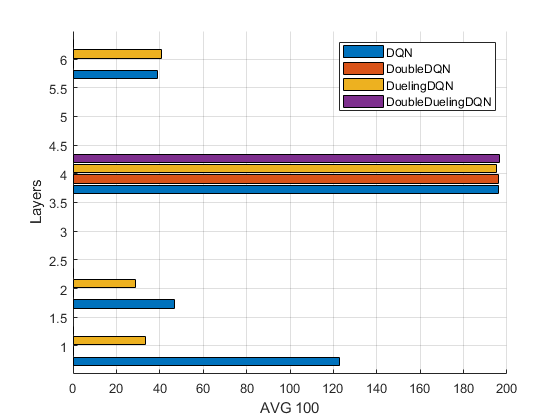



x = unique(N_Layers);

y = [];
for i = 1:length(x)
    idx = find([f_data.n_layers] == x(i));
    ty = [];
    for k = 1:length(archs)
        idxs = [];
        for j = 1:length(idx)
            if string(f_data(idx(j)).arch) == archs(k)
                idxs = [idxs,j];
            end
        end
        if ~isempty(idxs)
            target_data = f_data(idx(idxs));
            tty = [];
            for l = 1:length(target_data)
                tty = [tty,max(target_data(l).avg_scores100)];
            end
            ty = [ty,max(tty)];
        else
            ty = [ty,0];
        end
    end
    y = [y;ty];
end

% y

close all
f = figure;
grid on;
set(f,'Visible','on');
hold on

barh(x,y)
xlabel('AVG 100')
ylabel('Layers')
legend(archs)